# 03 HO: Numerical Integration

clear all; close all;

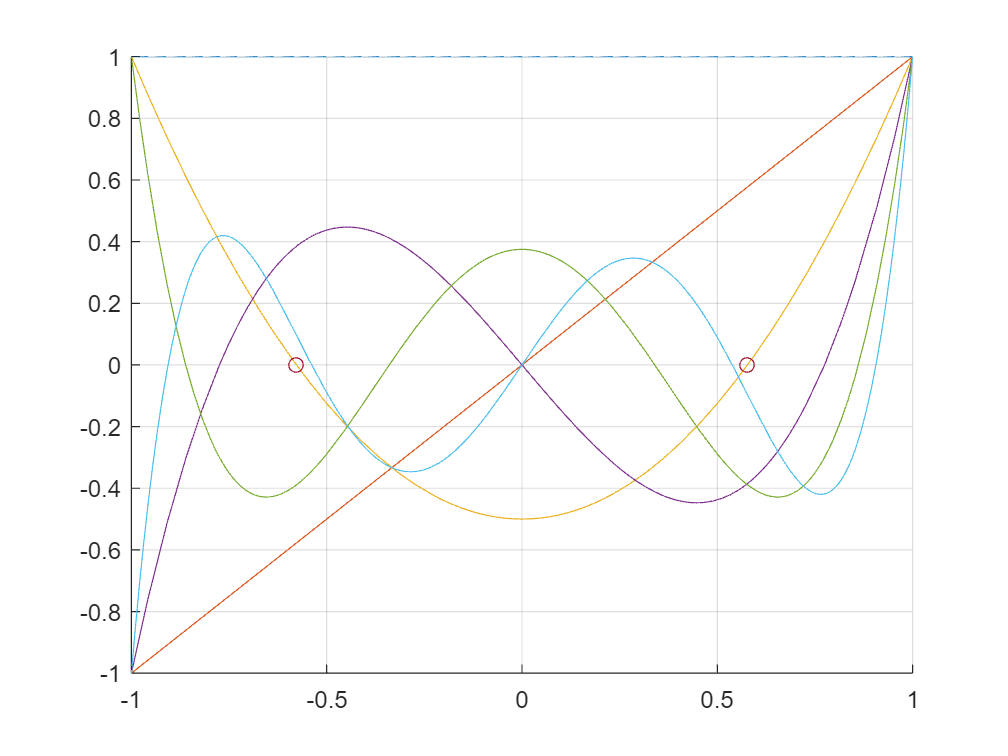

% Preparation: Legendre polynomials
f1 = figure; hold on; grid on;
for i = 0 : 5
    fhp = @(x) legendrePoly(x, i);
    fplot(fhp, [-1 1])
end

% Function to integrate
fx = @(x) -8 * x .^ 3 + 13 * x .^ 2 + 7 * x + 8;
% fx = @(x) 6 * x .^ 4 - 8 *  x .^ 3 + 13 * x .^ 2 + 7 * x + 8;

p = 3;
bounds = [-1 1];
% bounds = [a b];

% Choose integration order 
% n = 3;
n = ceil((p + 1) / 2);

% Compute integration points and weights
[xg, wg] = gaussianPoints(n);
scatter(xg, zeros(numel(xg), 1));

% Evaluate integral
res = 0;
for g = 1 : numel(xg)
    
    % transform r_g (standart space) to x_g
    xgr =   (bounds(2) - bounds(1)) / 2 * xg(g) + ...
            (bounds(2) + bounds(1)) / 2;

    % add new summand (1. compensate for bounds, 2. evaluate at x_g, 3. multiply weight to summand)
    res = res + ...
                (bounds(2) - bounds(1)) / 2 * fx(xgr) * wg(g);
end

res

res = 24.6667

## Additional functions

function P = legendrePoly(x, n)
    %{
        Evaluate and return Legendre polynomial
        INPUT
          x (array)   Evaluation points
          n (scalar)  Degree of polynomial
        OUTPUT
          P (array)   Polynomial values for input x
    %}    
    if n == 0
        P = ones(size(x));
    elseif n == 1
        P = x;
    else
        % recursive formultation
        P = ((2 * n - 1) * x .* legendrePoly(x, n - 1) - (n - 1) * legendrePoly(x, n - 2)) ./ n;
    end
end



function dP = legendrePolyDerivative(x, n)
    %{
        Evaluate and return derivative of Legendre polynomial
        INPUT
          x (array)   Evaluation points
          n (scalar)  Degree of polynomial derivative
        OUTPUT
          dP (array)  Derivatives for input x
    %}

    % recursive formultation
    dP = n / (x ^ 2 - 1) * (x * legendrePoly(x, n) - legendrePoly(x, n - 1));
end



function [xg, wg] = gaussianPoints(n)
    %{
        Compute gaussian points and weights for given integration order
        INPUT
          n (scalar, array)   Scalar or array of scalars for integration order in dimensions
        OUTPUT
          xg (array)          Array of gaussian points
          wg (array)          Weights for gaussian points xg
    %}

    % Newton-Rhapson method for finding roots of polynomial
    roots = zeros(floor(n / 2), 1);
    for i = 1 : floor(n / 2)
        % initial guess
        x0 = cos(pi * (i - 1 / 4) / (n + 1 / 2));

        % Newton's Method
        fhp     = @(x) legendrePoly(x, n);
        fhdp    = @(x) legendrePolyDerivative(x, n);

        x       = findRoot(fhp, fhdp, x0, 1e-9);
        roots(i)= x;
    end

    if mod(n, 2) == 0   % if order is even 
        xg = sort([-1 * roots; roots]);
    else
        xg = sort([-1 * roots; 0; roots]);
    end
    
    % Calculate weights
    wg = zeros(size(xg));
    for i = 1 : numel(xg)
        xi = xg(i);
        wg(i) = 2 / ((1 - xi ^ 2) * legendrePolyDerivative(xi, n) ^ 2);
    end
end



function xn = findRoot(f, df, x0, tolerance)
    %{
        Find roots of function f using Newton's method starting at x0
        INPUT
          f (function handle)     Function handle to function whose roots are to be determined
          df (function handle)    Derivative of function f
          x0  (scalar)            Start point for algorithm
          tolerance (scalar)      Tolerance for convergence check
        OUTPUT
          xn (scalar)             Root of f after convergence of algorithm
    %}

    xn = x0;
    nIter = 0;
    err = 1;
    while err > tolerance && nIter < 100 
        x = xn - f(xn) ./ df(xn);
        err = abs(x - xn);
        xn = x;
        nIter = nIter + 1;
    end
end